**Alberto León Luengo y José Miguel Jiménez García**

# **Laboratorio Tema 4 Ampliación de Matemática Aplicada:**

**Punto 1.**

Enunciado: Genere 16 puntos arbitrarios en el plano XY, dentro del cuadrado [0,10] x [0,10].

x = 10*rand(16,1);  % Generar 16 valores aleatorios en el rango [0,1]
y = 10*rand(16,1);  
plot(x,y,'o');       % Graficar los puntos
xlim([0,10]); ylim([0,10]); % Establecer los límites del gráfico

**Punto 2.**

Enunciado: Cree una función regr() cuya entrada sean los primeros diez puntos y cuya salida sea una recta en el plano XY que represente la regresión linear de estos datos con el método de mínimos cuadrados.

% En el fichero regr.mlx

**Punto 3.**

Enunciado: A continuación lea los otros seis puntos y cree una función regrRecurrente() que utilice el método usado en la clase de teoría para actualizar la regresión linear de la siguiente manera: 

– Primero añadimos un punto y actualizamos la anterior regresión linear de diez puntos. 

– Luego añadimos los siguientes dos puntos y actualizamos la anterior regresión linear de once puntos. 

– Finalmente, añadimos los últimos tres puntos y actualizamos la anterior regresión linear de trece puntos. 

– En esta parte utilice el método usado en clase para actualizar la regresión linear. No puede hacer la regresión de los once, trece y dieciseis puntos, respectivamente, desde cero, sinque que tiene que usar el método de clase, aprovechando los cálculos de cada una de las regresiones anteriores.

% En el fichero regrRecurrente.mlx

**Punto 4.**

Enunciado: Cree otra función regrRecurrenteCov() que añada cierta aleatoriedad al problema mediante una matriz de covarianza arbitraria (asegúrese de que es una verdadera matriz de covarianza) a la funciones anteriores. Use la parte de teoría sobre filtros de Kalman para ello.

% En el fichero regrRecurrenteCov.mlx

**Punto 5.**

Enunciado: Representa cada una de las regresiones lineares.

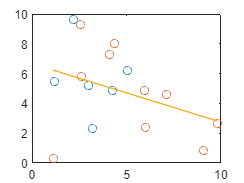

n = 11

b = 6.9910

n = 13

b = 6.9471

n = 16

b = 7.0229

% regr(x,y);
% [a,b] = regrRecurrente(x,y);

% [a,b] = regrRecurrenteCov(x,y,covarianza);

**Punto 6.**

Enunciado: Utilice las funciones ya implementadas para resolver estos mismos problemas y compare las soluciones de estas funciones con las soluciones de sus funciones así como los tiempos de ejecución.

% La función timeit() llama a la función varias veces y devuelve la mediana
% de las mediciones (toma un identificador de la función a medir y devuelve 
% el tiempo de ejecución habitual en segundos).
% Tiempo de ejecución de la función regr().
% f1 = @() regr(x,y);
% timeit(f1)
% Tiempo de ejecución de la función regrRecurrente().
% f2 = @() regrRecurrente(x,y);
% timeit(f2)
% Tiempo de ejecución de la función regrRecurrentCov().
% f3 = @() regrRecurrenteCov(x,y,covarianza);
% timeit(f3);

**Punto 7.**

Enunciado: Comente las diferencias en los tiempos de ejecución.